# Eksamen 2015E Løsning

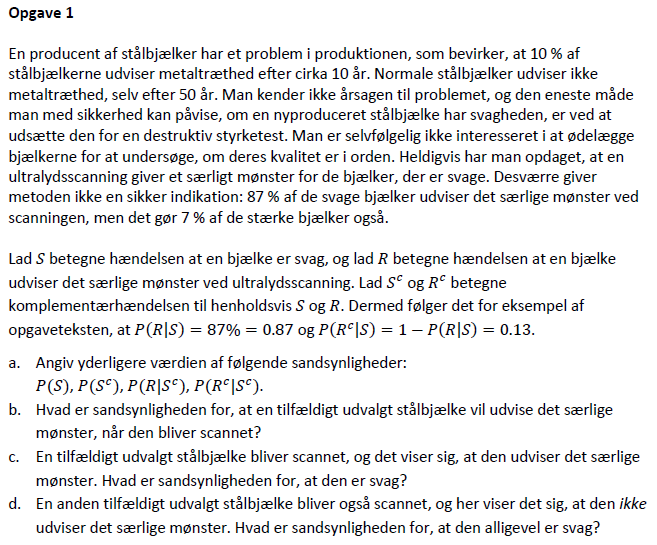

clc; clear all;

% Data fra opgaven
pR_S = 0.87;         % Bjælken udviser mønstret, givet den er svag
rRc_S = 1 - pR_S;    % Bjælken udviser IKKE mønstret, givet den er svag

% Opgave a
pS = 0.10;          % Ssh for svag bjælke. Givet fra opgaven
pSc = 1 - pS;       % P ikke svag - altså stærk
pR_Sc = 0.07;       % Ssh for den viser mønster og ikke er svag. Givet fra opgaven
pRc_Sc = 1 - pR_Sc; % Ssh for den ikke udviser mønster givet den er stærk


% Opgave b - Totale lov om ssh
pR = pR_S * pS + pR_Sc * pSc    % Ssh for udviser mønster og er svag plus udviser mønster og er stærk

% Opgave c - bayes lov
pSR = pR_S * pS / pR      % Ssh for den scannes og er svag

% Opgave d - komplimentær værdier i bayes lov
pR_Sc = rRc_S * pS/(1 - pR)



## Opgave 2

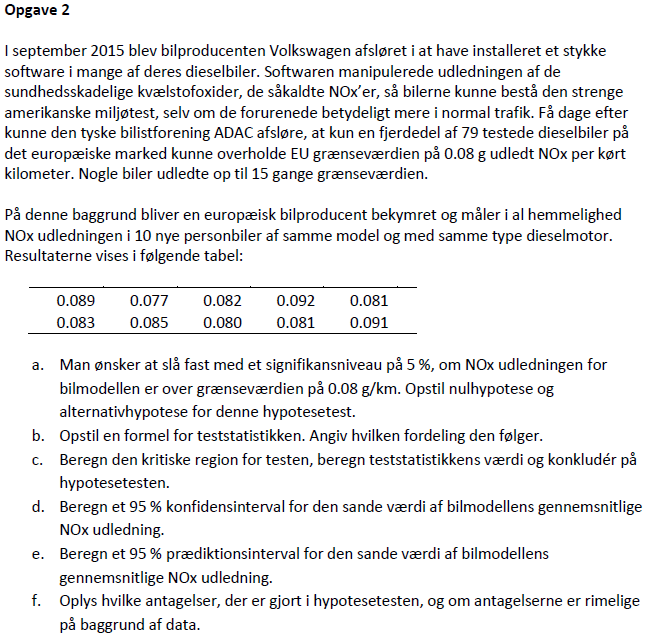

clc; clear;

% data indlæses
data = xlsread("M4STI1_2015E_data.xlsx","A:A");

Stikprøvemiddelværdiens formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{n}$$

-----------------------------------------------------------------
Stikprøvevariansens formel


$$s=\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}$$

-----------------------------------------------------------------
Stikprøvestandardafvigelsens formel


$$s=\sqrt{\frac{n\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{n\,\left(n-1\right)}}$$

-----------------------------------------------------------------
t-værdiens formel


$$t_{\mathrm{df},\alpha }=-\mathrm{tinv}\,\left(\alpha \,n-1\right)$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t=\frac{\bar{y}-\mu_{0}}{s\,\sqrt{n}}$$

----------------------------------------------------------------------------------------------
    Datanavn    Middelværdi    Spredning     Standardafv.    Datapunkter
      navn                                                              
    ________    ___________    __________    ____________    ___________

    {'data'}      0.0841       2.5211e-05     0.0050211          10     

    Frihedsgrader    Teststatistik      t0      p-værdi    h-værdi
    _____________    _____________    ______    _______    _______

          9             2.5822        1.8331    0.9852        0   



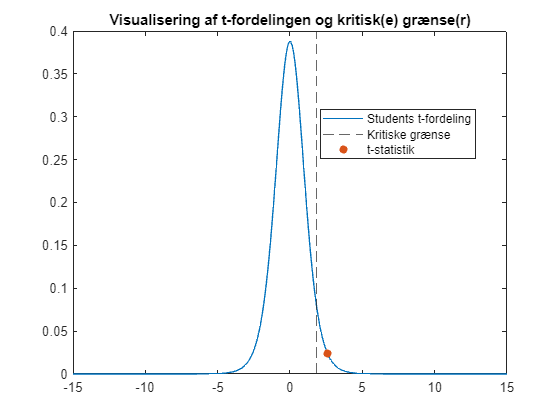

Da h = 0 forkastes nulhypotesen ikke
Ydermere ses det også at t-værdien 2.5822 ikke overstiger den kritiske grænse på 1.8331


data = [0.0890 0.0770 0.0820  0.0920 0.0810 0.0830 0.0850 0.0800 0.0810 0.0910];


StudentTestMiddel(data, 0.08, "left", 95)